*HW4: Configuration Space (Matlab)*

*Arjan Gupta*

*2/52023*

close all; clear; clc;

# Configuration Space Assignment

In this assignment, we will replicate some of the functionality from Prof. Ron Alterovitz's website program. We will create a program consists of a 2D Robotic Manipulator and map the workspace obstacle to the configuration space.

First, we build our robot. with fixed link lengths and DH params.

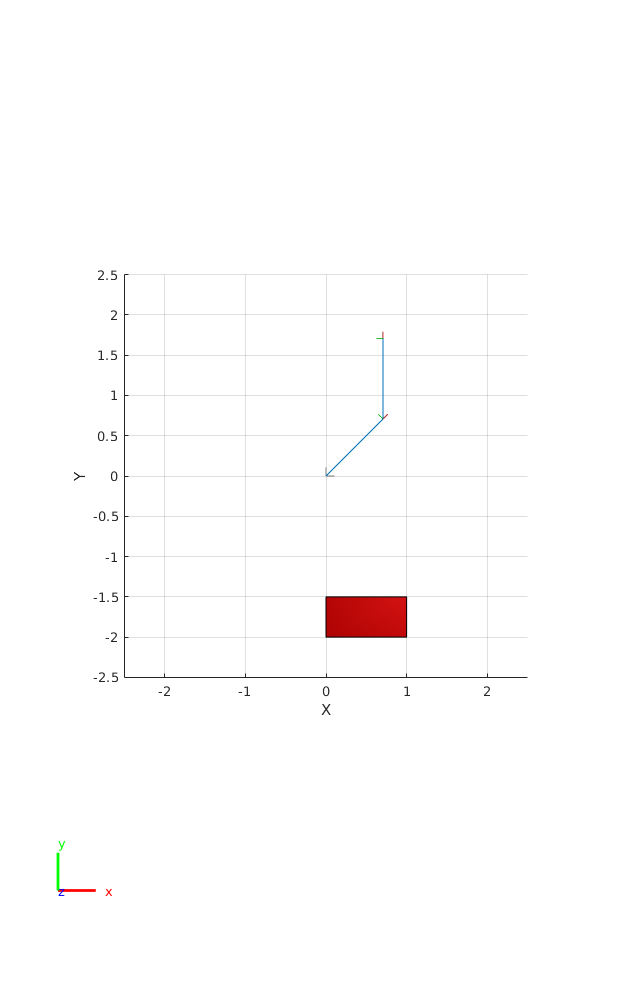

link_length1 = 1;
link_length2 = 1;
theta1 = 0;
theta2 = 0;
twolink_robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
dhparams = [link_length1 0 0 theta1
            link_length2 0 0 theta2]; % a alpha d theta
setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
body1.Joint = jnt1;
body2.Joint = jnt2;
addBody(twolink_robot, body1, 'base');
addBody(twolink_robot, body2, 'body1');
% showdetails(twolink_robot);
% ax1 = uiaxes(plot_grid)
% ax1.Properties = ''
global config 
config = homeConfiguration(twolink_robot);
config(1).JointPosition = deg2rad(45);
config(2).JointPosition = deg2rad(45);
show(twolink_robot, config);
view(2)
ax = gca;
ax.Projection = 'orthographic';
global obstacle1_x
global obstacle1_y
obstacle1_x = [ 0,    0,    1,  1];
obstacle1_y = [-2, -1.5, -1.5, -2];
draw_obstacles(ax);

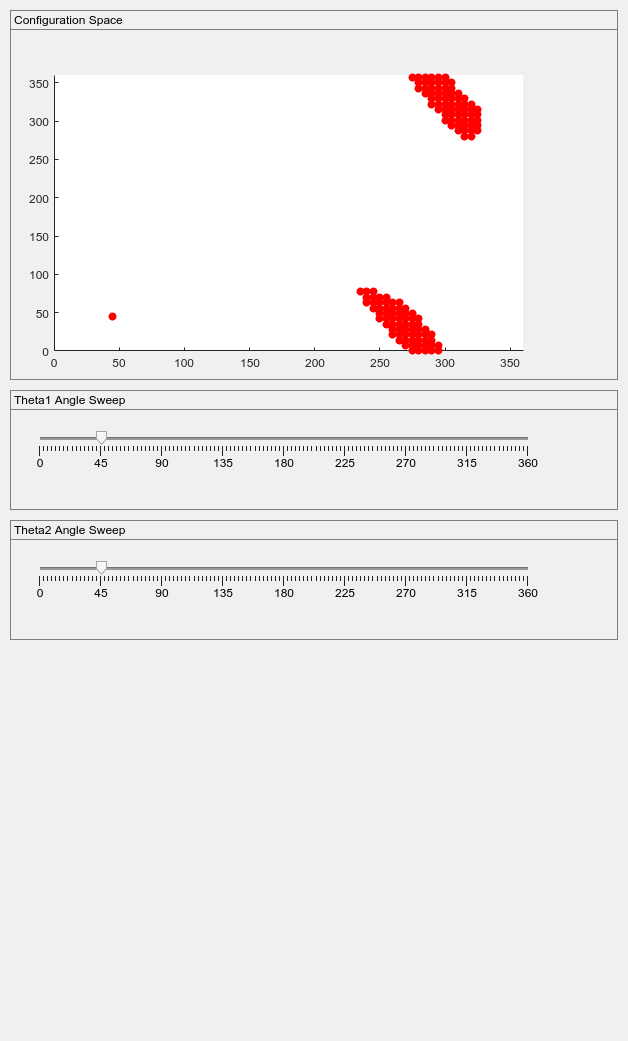


% Create view for plots and sliders
fig = uifigure('Position',[100 100 500 650]);
grid1 = uigridlayout(fig,[3 1]);
grid1.RowHeight = {370 120 120};

% CSPACE PLOT
plot_panel = uipanel(grid1,"Title", "Configuration Space");
% plot_grid = uigridlayout(plot_panel, [1 1]);
ax2 = uiaxes(plot_panel,"XLim",[0 360],"YLim",[0 360]);
y = 45;
x = 45;
% plt = scatter(ax2,x,y,'b+');
global cspace_shape_x
global cspace_shape_y
cspace_shape_x = x;
cspace_shape_y = y;
obstacle1_y_max = max(obstacle1_y);
obstacle1_y_min = min(obstacle1_y);
obstacle1_x_max = max(obstacle1_x);
obstacle1_x_min = min(obstacle1_x);
collision_config = homeConfiguration(twolink_robot);
for theta1 = 220:5:360
    collision_config(1).JointPosition = deg2rad(theta1);
    for theta2 = 0:7:360
        collision_config(2).JointPosition = deg2rad(theta2);
        T2 = getTransform(twolink_robot, collision_config, 'body2', 'base');
        tip_x = T2(1,4);
        tip_y = T2(2,4);
        if (tip_y < obstacle1_y_max && tip_y > obstacle1_y_min && tip_x < obstacle1_x_max && tip_x > obstacle1_x_min)
            cspace_shape_x = [cspace_shape_x theta1];
            cspace_shape_y = [cspace_shape_y theta2];
        end
    end
end
plt = scatter(ax2,cspace_shape_x,cspace_shape_y,'r','filled');

% SLIDERS
theta1_panel = uipanel(grid1, 'Title', 'Theta1 Angle Sweep');
sld1 = uislider(theta1_panel,...
    'Value',45,...
    'Position',[30 70 360 3],...
    'Limits',[0 360],...
    'MajorTicks',[0 45 90 135 180 225 270 315 360],...
    'ValueChangedFcn',@(sld1,event) changeXVal(sld1, plt, twolink_robot));
theta2_panel = uipanel(grid1, 'Title', 'Theta2 Angle Sweep');
sld2 = uislider(theta2_panel,...
    'Value',45,...
    'Position',[30 70 360 3],...
    'Limits',[0 360],...
    'MajorTicks',[0 45 90 135 180 225 270 315 360],...
    'ValueChangedFcn',@(sld2,event) changeYVal(sld2, plt, twolink_robot));

function changeYVal(sld, plt, robot)
    global cspace_shape_x
    global cspace_shape_y
    cspace_shape_y(1) = sld.Value;
    set(plt,'YData',cspace_shape_y);
    global config
    config(2).JointPosition = deg2rad(sld.Value);
    show(robot, config,'PreservePlot',false);
    view(2)
    ax = gca;
    ax.Projection = 'orthographic';
    drawnow;
    draw_obstacles(ax);
end

function changeXVal(sld, plt, robot)
    global cspace_shape_x
    global cspace_shape_y
    cspace_shape_x(1) = sld.Value;
    set(plt,'XData',cspace_shape_x);
    global config
    config(1).JointPosition = deg2rad(sld.Value);
    show(robot, config,'PreservePlot',false);
    view(2)
    ax = gca;
    ax.Projection = 'orthographic';
    drawnow;
    draw_obstacles(ax);
end

function draw_obstacles(axis)
    global obstacle1_x
    global obstacle1_y
    patch(axis,obstacle1_x,obstacle1_y,'red')
end